clc 
clear
runTime=2.5; %Tiempo que dura la simulacion de Simulink

### Periodo de Muestreo

Ts=25/1000; %buscamos un Ts que haga que Pd sea inversamente estable
ts=Ts;

### Modelo de Planta

%%Modelado
s=tf('s');
z=tf('z', Ts);
P = 0.075/(0.035*s+1)/(0.2*s+1)

P =
 
           0.075
  -----------------------
  0.007 s^2 + 0.235 s + 1
 
Continuous-time transfer function.



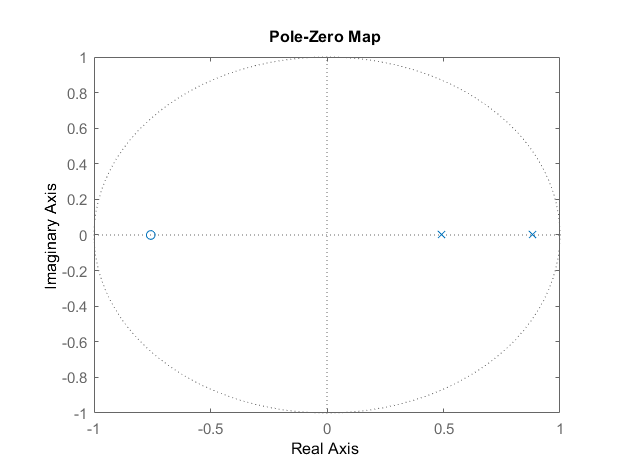

Pd=c2d(P, Ts, 'zoh');
pzmap(Pd)% O dentro del circulo unidad -> estable

delay = exp(-ts*s/2);
Pm = P*delay;

### 3 CONTROL PID 3.1 PID - DISEÑO

Fm=50

Fm = 50

wo=30;
f=0.1

f = 0.1000

Fpi=-10;
b=1;
DerivadaError=1;% 1 error o salida

Modelo analógico modificado.

Fa = tf(1,1);
%% Control PID eje X

I=-1/(wo*tand(Fpi));
%Hallar ganancia Y fase del control
Fic=-180+Fm-angle(freqresp(Pm,wo))*(180/pi);
Ac=1/abs(freqresp(Pm, wo));
%control PD
Fpd=Fic-Fpi;

fmax=(1-sind(Fpd))/(1+sind(Fpd));
if f>fmax
    f=fmax;
end

D=((1/f-1)/(2*tand(Fpd))-sqrt(((1/f-1)/(2*(tand(Fpd))))^2-1/f))/wo;
Kp=Ac*cosd(Fpi)*(sqrt(1+(f*wo*D)^2))/(sqrt(1+(wo*D)^2));

%conversión modelo serie a paralelo:
mu=1+(1-f)*D/I;
K=mu*Kp;
Td=((1/mu)-f)*D;
Ti=mu*I;
N=(1/(mu*f))-1;
%fórmula para hallar b 
C=K*(1+1/(Ti*s)+(Td*s)/(1+Td*s/N));
G_pid=minreal(C*Pm);

%sin ponderación y diferencial sobre error
%Cr_pid=C_pid;
if(DerivadaError==1)
    %ponderación sobre error
    Cr=K*(b+1/(Ti*s)+(Td*s)/(1+Td*s/N));
else C=K*(1+1/(Ti*s)+(Td*s)/(1+Td*s/N));
    %con ponderación y diferencial sobre salida
    Cr=K*(b+1/(Ti*s));
end
zpk(C)

ans =
 
  984.11 (s+48.02) (s+5.29)
  -------------------------
         s (s+480.2)
 
Continuous-time zero/pole/gain model.



zpk(Cr)

ans =
 
  984.11 (s+48.02) (s+5.29)
  -------------------------
         s (s+480.2)
 
Continuous-time zero/pole/gain model.



## Discretizacion

%sa=(z-1)/Ts %forward Euler dervi Ad Int retraso <- casi siempre mejor
%sa=(z-1)/(z*Ts)%Backward Euler dervi ret Int adelanto <- si hay ringing
sa=2*(z-1)/Ts/(z+1)%Trapezoidal

sa =
 
      2 z - 2
  ---------------
  0.025 z + 0.025
 
Sample time: 0.025 seconds
Discrete-time transfer function.



Cd=minreal(K*(1+1/(Ti*sa)+(Td*sa)/(1+Td*sa/N)));
if(DerivadaError==1)
    %ponderación saobre error
    Crd=minreal(K*(b+1/(Ti*sa)+(Td*sa)/(1+Td*sa/N)));
else
    %con ponderación y diferencial saobre saalida
    Crd=minreal(K*(b+1/(Ti*sa)));
end
zpk(Cd)

ans =
 
  239.77 (z-0.876) (z-0.2498)
  ---------------------------
       (z-1) (z+0.7144)
 
Sample time: 0.025 seconds
Discrete-time zero/pole/gain model.



zpk(Crd)

ans =
 
  239.77 (z-0.876) (z-0.2498)
  ---------------------------
       (z-1) (z+0.7144)
 
Sample time: 0.025 seconds
Discrete-time zero/pole/gain model.



## 3.2 PID - ANÁLISIS

G_pid=minreal(Cd*Pd);
F_ry_pid=minreal(Crd*Pd/(1+G_pid));
%da error using minreal ( improper model) F_ru_pid=minreal(Cr/(1+G_pid));
F_dy_pid=minreal(-Pd/(1+G_pid));
F_du_pid=minreal(Pd*Cd/(1+G_pid));
%parámetros
%[Am_pid,Fm_pid,wu_pid,wo_pid] = margin(G_pid)

% Sensibilidad
S_pid=minreal(1/(1+G_pid));
% Pulsacion de maxima sensibilidad
ws_pid=fminsearch(@(w) -abs(freqresp(S_pid,w)),1)

ws_pid = 50.7888

% Maxima sensibilidad
Ms_pid=20*log10(abs(freqresp(S_pid,ws_pid)))

Ms_pid = 3.4534


% Pulsacion de resonancia
wr_pid=fminsearch(@(w) -abs(freqresp(F_ry_pid,w)),1)

wr_pid = 25.7596

% Pico de resonancia
Mr_pid=20*log10(abs(freqresp(F_ry_pid,wr_pid)))-20*log10(dcgain(F_ry_pid))

Mr_pid = 1.2729

ModeloMixto no podemos hacer ltiview

PlotSimulation("PID","Control_PID_sim.slx")

result =   Simulink.SimulationOutput:

                   tout: [250153x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


ans =   Simulink.SimulationOutput:

                   tout: [250153x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


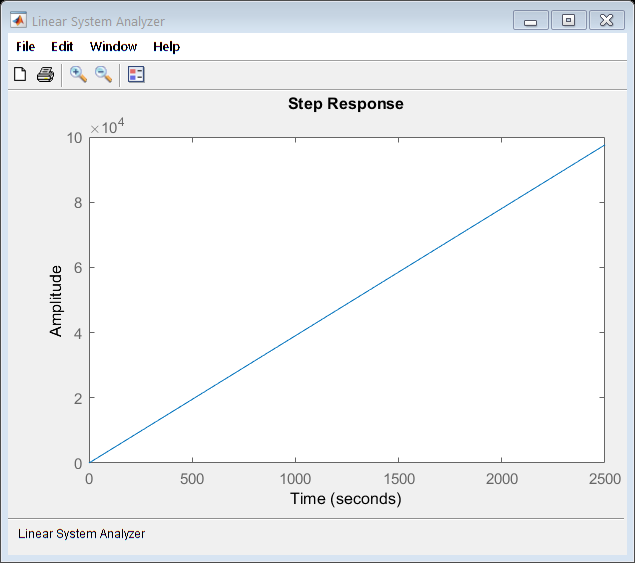

ltiview(G_pid)

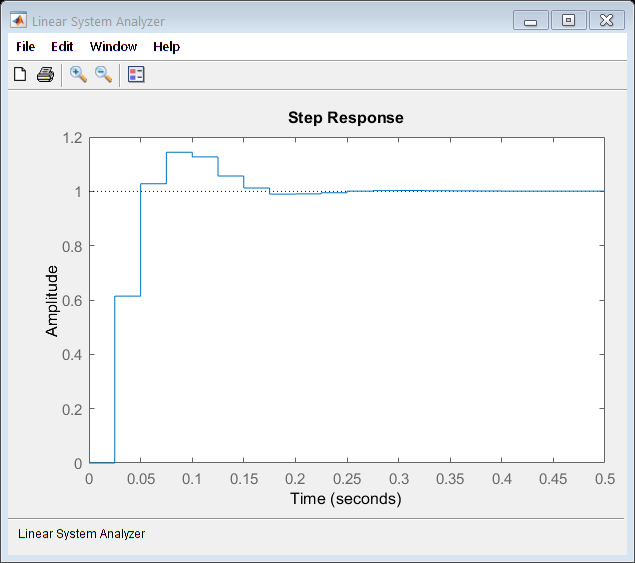

ltiview(F_ry_pid) % maxima resonanca ojo db desde perm no 0db